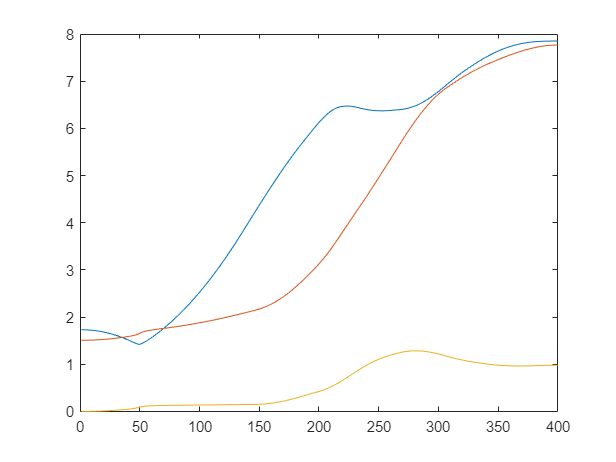

plot(COM_traj')


M = diag([10 10 1/12*10*(0.5^2 + 1^2)])

M =    10.0000         0         0
         0   10.0000         0
         0         0    1.0417




% Define location of robots

% P_C_mat = [ 0.5 -0.5
%               0    0]
P_C_mat = [ 0.5 -0.5 0
              0    0 0.25]

P_C_mat =     0.5000   -0.5000         0
         0         0    0.2500


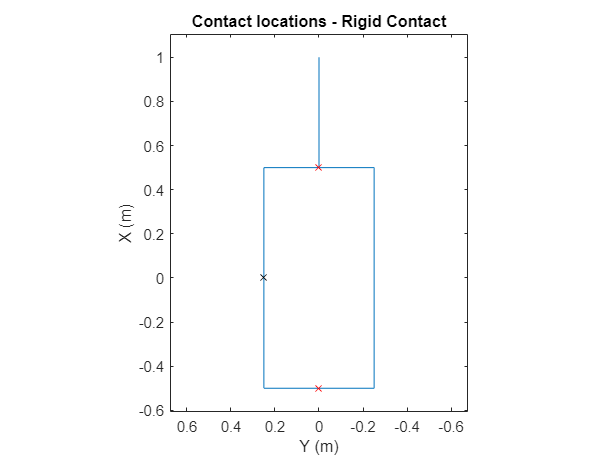


plot_cart([0;0;0]); hold on
for i = 1:width(P_C_mat)
if i == 3
    style = 'kx';
else
    style = 'rx';
end
plot(P_C_mat(1,i), P_C_mat(2,i), style);
end
view(-90,90);
axis equal padded
hold off
title("Contact locations - Rigid Contact")
xlabel("X (m)")
ylabel("Y (m)")



G = [];
for i = 1:width(P_C_mat)
G = [G rigid_grasp_map(P_C_mat(:,i))];
end
G

G =     1.0000         0    1.0000         0    1.0000         0
         0    1.0000         0    1.0000         0    1.0000
         0    0.5000         0   -0.5000   -0.2500         0


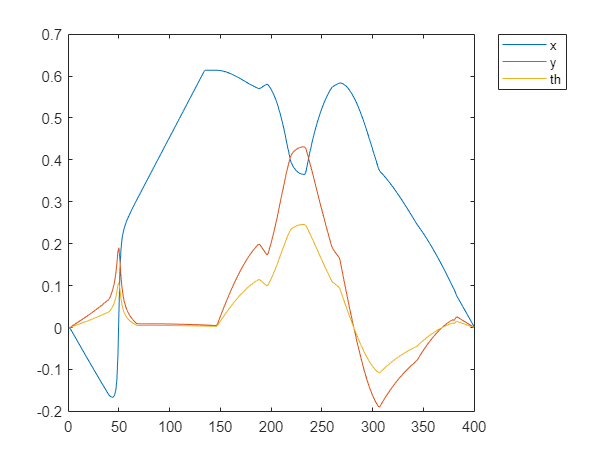

% Calculate required force in cart frame
v_R = NaN([3 N_steps]);
v_R(:,1) = [0;0;0];
v_W = NaN([3 N_steps]);
v_W(:,1) = [0;0;0];
for i = 2:N_steps
   v = (COM_traj(:,i) - COM_traj(:,i-1))/Ts;
   v_R(1:2,i) = rot2(-COM_traj(3,i))*v(1:2);
   v_R(3,i) = v(3);
   v_W(:,i) = v;
end

plot(v_R')
legend(["x","y","th"])

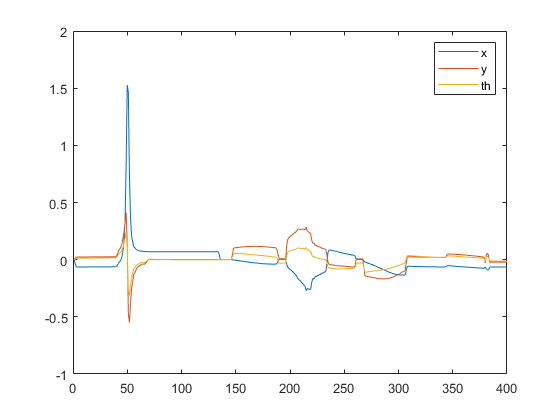


a_R = NaN([3 N_steps]);
a_W = NaN([3 N_steps]);
a_R(:,1) = [0;0;0];
a_W(:,1) = [0;0;0];

for i = 2:N_steps
   a = (v_W(:,i) - v_W(:,i-1))/Ts;
   a_R(1:2,i) = rot2(-COM_traj(3,i))*a(1:2);
   a_R(3,i) = a(3);
   a_W(:,i) = a;
end

plot(a_R')
legend(["x","y","th"])

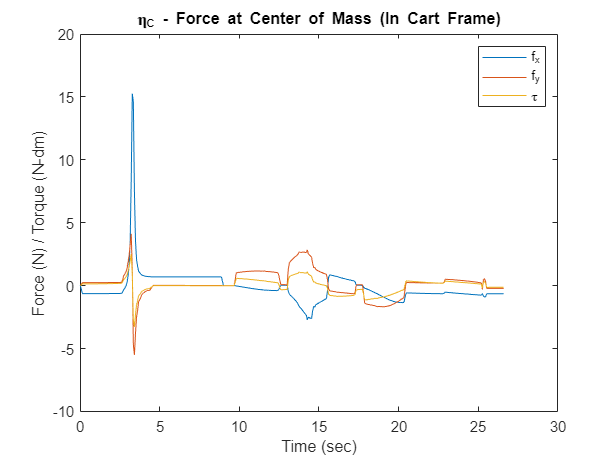


force_R = M*a_R;

plot(tt, force_R(1:2,:)'); hold on
plot(tt, 10*force_R(3,:)'); hold off
legend(["f_x","f_y","\tau"])
xlabel("Time (sec)")
ylabel("Force (N) / Torque (N-dm)")
title("\eta_C - Force at Center of Mass (In Cart Frame)")

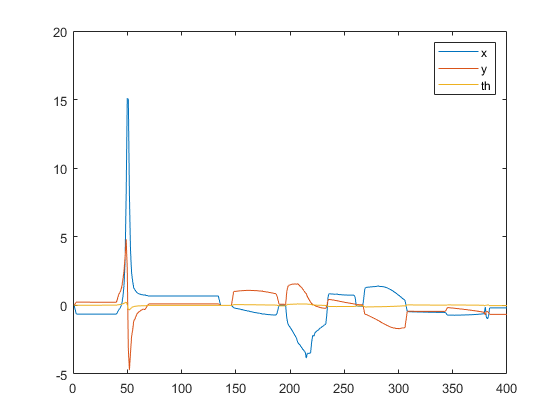


force_W = M*a_W;
plot(force_W')
legend(["x","y","th"])

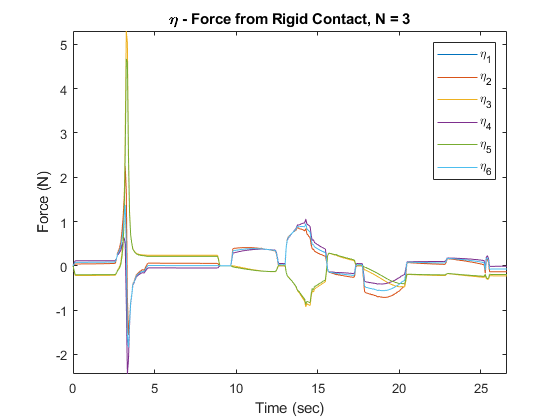





robot_force_R = [];
for i = 1:N_steps
    robot_force_R(:,i) = pinv(G)*force_R(:,i);
end
plot(tt, robot_force_R')
legend('\eta_' + string(1:width(G)))
title("\eta - Force from Rigid Contact, N = " + width(G)/2)
xlabel("Time (sec)")
ylabel("Force (N)")
axis tight

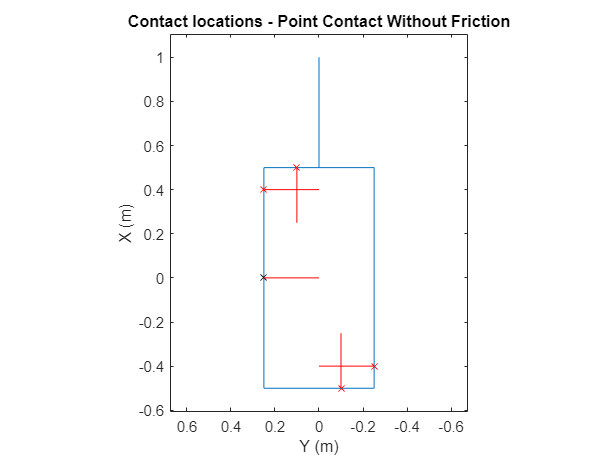

% Point contact

% P_C_mat = [0.5 0.4 -0.5 -0.4
%            0.1 0.25 -0.1 -0.25];
% N_mat = [-1  0 1 0
%           0 -1 0 1];

P_C_mat = [0.5 0.4 -0.5 -0.4   0 
           0.1 0.25 -0.1 -0.25 0.25];
N_mat = [-1  0 1 0 0
          0 -1 0 1 -1];


plot_cart([0;0;0]); hold on
for i = 1:width(P_C_mat)
if i == 5
    style = 'kx';
else
    style = 'rx';
end
plot(P_C_mat(1,i), P_C_mat(2,i), style);
plot(P_C_mat(1,i) + [0 N_mat(1,i)]*0.25,P_C_mat(2,i) + [0 N_mat(2,i)]*0.25, 'r') 
end
view(-90,90);
axis equal padded
hold off
title("Contact locations - Point Contact Without Friction")
xlabel("X (m)")
ylabel("Y (m)")


G = [];
for i = 1:width(P_C_mat)
G = [G point_contact_map(P_C_mat(:,i), N_mat(:,i))];
end
G

G =    -1.0000         0    1.0000         0         0
         0   -1.0000         0    1.0000   -1.0000
    0.1000   -0.4000    0.1000   -0.4000         0


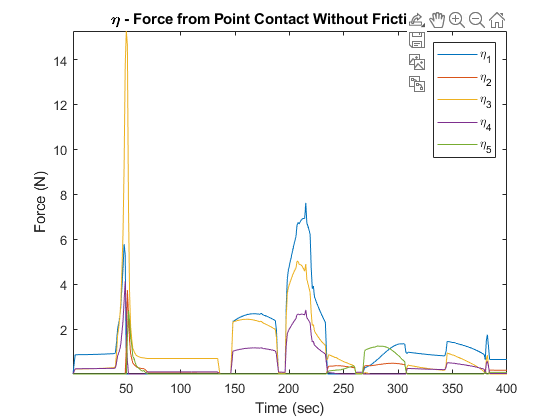


robot_force_R = [];
for i = 1:N_steps
    robot_force_R(:,i) = pos_span(force_R(:,i), G);
end
plot(robot_force_R')
legend('\eta_' + string(1:width(G)), Location="northeast")
title("\eta - Force from Point Contact Without Friction, N = " + width(G))
xlabel("Time (sec)")
ylabel("Force (N)")
axis tight

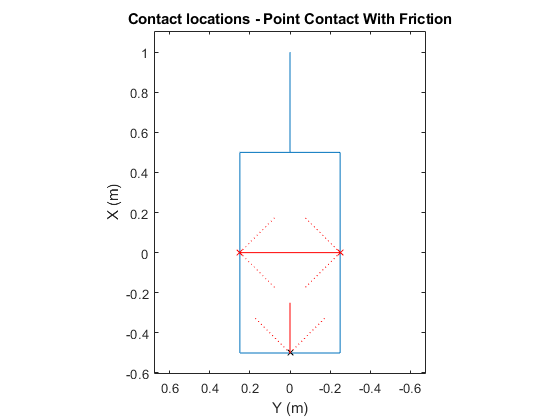

% Point contact with 45 degree friction

P_C_mat = [0        0 -0.5
           0.25 -0.25    0];
N_mat = [0  0  1
         -1  1 0];

% P_C_mat = [0        0 
%            0.25 -0.25  ];
% N_mat = [0  0 
%          -1  1];

plot_cart([0;0;0]); hold on

N_mat_pos_rot = rot2(deg2rad(45))*N_mat;
N_mat_neg_rot = rot2(deg2rad(-45))*N_mat;
for i = 1:width(P_C_mat)
if i == 3
    style = 'kx';
else
    style = 'rx';
end
plot(P_C_mat(1,i), P_C_mat(2,i), style);
plot(P_C_mat(1,i) + [0 N_mat(1,i)]*0.25,P_C_mat(2,i) + [0 N_mat(2,i)]*0.25, 'r') 
plot(P_C_mat(1,i) + [0 N_mat_pos_rot(1,i)]*0.25,P_C_mat(2,i) + [0 N_mat_pos_rot(2,i)]*0.25, ':r') 
plot(P_C_mat(1,i) + [0 N_mat_neg_rot(1,i)]*0.25,P_C_mat(2,i) + [0 N_mat_neg_rot(2,i)]*0.25, ':r') 
end
view(-90,90);
axis equal padded
hold off
title("Contact locations - Point Contact With Friction")
xlabel("X (m)")
ylabel("Y (m)")




G = [];
for i = 1:width(P_C_mat)
G = [G point_contact_friction_map(P_C_mat(:,i), N_mat(:,i), rad2deg(45))];
end
G

G =     0.8061   -0.8061   -0.8061    0.8061   -0.5918   -0.5918
    0.5918    0.5918   -0.5918   -0.5918    0.8061   -0.8061
   -0.2015    0.2015   -0.2015    0.2015   -0.4030    0.4030


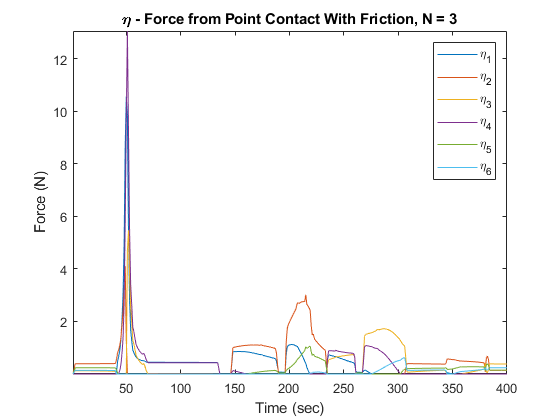


robot_force_R = [];
for i = 1:N_steps
    robot_force_R(:,i) = pos_span(force_R(:,i), G);
end
plot(robot_force_R')

legend('\eta_' + string(1:width(G)), Location="northeast")
title("\eta - Force from Point Contact With Friction, N = " + width(G)/2)
xlabel("Time (sec)")
ylabel("Force (N)")
axis tight

function G = rigid_grasp_map(p_Ci)
G = [1 0
     0 1
     -p_Ci(2) p_Ci(1)];
end

function G = point_contact_map(p_Ci, n_i)
cross3 = cross([p_Ci;0], [n_i;0]);
G = [n_i
     cross3(3)];
end

function G = point_contact_friction_map(p_Ci, n_i, phi)
G = [point_contact_map(p_Ci, rot2(phi)*n_i) point_contact_map(p_Ci, rot2(-phi)*n_i)];
end


function eta = pos_span(eta_C, G)
N_force = width(G);

% lower bound x >= lb
lb = zeros([N_force,1]);

% equality constraint A_eq x = b_eq
A_eq = G;
b_eq = eta_C;

% Quadratic const 1/2 x' H x + f'x
H = eye(N_force);
f = zeros([N_force 1]);

options = optimoptions('quadprog','Display','off');
eta = quadprog(H,f,[],[],A_eq,b_eq, lb, [], [],options);
end